# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 31-Dec-2024 14:29:21

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = [
    imageInputLayer([520 704 1],"Name","Input_data")
    convolution2dLayer([7 7],64,"Name","conv1","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","bn1")
    reluLayer("Name","node_8")
    maxPooling2dLayer([3 3],"Name","node_9","Padding",[1 1 1 1],"Stride",[2 2])];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],64,"Name","res2a_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn2a_branch2a')
    reluLayer("Name","relu2a_branch2a")
    convolution2dLayer([3 3],64,"Name","res2a_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn2a_branch2b')
    reluLayer("Name","relu2a_branch2b")
    convolution2dLayer([1 1],256,"Name","res2a_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn2a_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],256,"Name","res2a_branch1","Padding","same")
    batchNormalizationLayer("Name",'bn2a_branch1')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_16")
    reluLayer("Name","node_17")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],64,"Name","res2b_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn2b_branch2a')
    reluLayer("Name","relu2b_branch2a")
    convolution2dLayer([3 3],64,"Name","res2b_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn2b_branch2b')
    reluLayer("Name","relu2b_branch2b")
    convolution2dLayer([1 1],256,"Name","res2b_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn2b_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_23")
    reluLayer("Name","node_24")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],64,"Name","res2c_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn2c_branch2a')
    reluLayer("Name","relu2c_branch2a")
    convolution2dLayer([3 3],64,"Name","res2c_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn2c_branch2b')
    reluLayer("Name","relu2c_branch2b")
    convolution2dLayer([1 1],256,"Name","res2c_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn2c_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_30")
    reluLayer("Name","node_31")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],512,"Name","res3a_branch1","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name",'bn3a_branch1')];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],128,"Name","res3a_branch2a","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name",'bn3a_branch2a')
    reluLayer("Name","relu3a_branch2a")
    convolution2dLayer([3 3],128,"Name","res3a_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn3a_branch2b')
    reluLayer("Name","relu3a_branch2b")
    convolution2dLayer([1 1],512,"Name","res3a_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn3a_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_38")
    reluLayer("Name","node_39")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],128,"Name","res3b_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn3b_branch2a')
    reluLayer("Name","relu3b_branch2a")
    convolution2dLayer([3 3],128,"Name","res3b_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn3b_branch2b')
    reluLayer("Name","relu3b_branch2b")
    convolution2dLayer([1 1],512,"Name","res3b_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn3b_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_45")
    reluLayer("Name","node_46")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],128,"Name","res3c_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn3c_branch2a')
    reluLayer("Name","relu3c_branch2a")
    convolution2dLayer([3 3],128,"Name","res3c_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn3c_branch2b')
    reluLayer("Name","relu3c_branch2b")
    convolution2dLayer([1 1],512,"Name","res3c_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn3c_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_52")
    reluLayer("Name","node_53")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],128,"Name","res3d_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn3d_branch2a')
    reluLayer("Name","relu3d_branch2a")
    convolution2dLayer([3 3],128,"Name","res3d_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn3d_branch2b')
    reluLayer("Name","relu3d_branch2b")
    convolution2dLayer([1 1],512,"Name","res3d_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn3d_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_59")
    reluLayer("Name","node_60")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],1024,"Name","res4a_branch1","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name",'bn4a_branch1')];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],256,"Name","res4a_branch2a","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name",'bn4a_branch2a')
    reluLayer("Name","relu4a_branch2a")
    convolution2dLayer([3 3],256,"Name","res4a_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn4a_branch2b')
    reluLayer("Name","relu4a_branch2b")
    convolution2dLayer([1 1],1024,"Name","res4a_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn4a_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_67")
    reluLayer("Name","node_68")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],256,"Name","res4b_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn4b_branch2a')
    reluLayer("Name","relu4b_branch2a")
    convolution2dLayer([3 3],256,"Name","res4b_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn4b_branch2b')
    reluLayer("Name","relu4b_branch2b")
    convolution2dLayer([1 1],1024,"Name","res4b_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn4b_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_74")
    reluLayer("Name","node_75")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],256,"Name","res4c_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn4c_branch2a')
    reluLayer("Name","relu4c_branch2a")
    convolution2dLayer([3 3],256,"Name","res4c_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn4c_branch2b')
    reluLayer("Name","relu4c_branch2b")
    convolution2dLayer([1 1],1024,"Name","res4c_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn4c_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_81")
    reluLayer("Name","node_82")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],256,"Name","res4d_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn4d_branch2a')
    reluLayer("Name","relu4d_branch2a")
    convolution2dLayer([3 3],256,"Name","res4d_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn4d_branch2b')
    reluLayer("Name","relu4d_branch2b")
    convolution2dLayer([1 1],1024,"Name","res4d_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn4d_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_88")
    reluLayer("Name","node_89")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],256,"Name","res4e_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn4e_branch2a')
    reluLayer("Name","relu4e_branch2a")
    convolution2dLayer([3 3],256,"Name","res4e_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn4e_branch2b')
    reluLayer("Name","relu4e_branch2b")
    convolution2dLayer([1 1],1024,"Name","res4e_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn4e_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_95")
    reluLayer("Name","node_96")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],256,"Name","res4f_branch2a","Padding","same")
    batchNormalizationLayer("Name",'bn4f_branch2a')
    reluLayer("Name","relu4f_branch2a")
    convolution2dLayer([3 3],256,"Name","res4f_branch2b","Padding","same")
    batchNormalizationLayer("Name",'bn4f_branch2b')
    reluLayer("Name","relu4f_branch2b")
    convolution2dLayer([1 1],1024,"Name","res4f_branch2c","Padding","same")
    batchNormalizationLayer("Name",'bn4f_branch2c')];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","node_102")
    reluLayer("Name","feature_out")];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

net = connectLayers(net,"node_9","res2a_branch2a");
net = connectLayers(net,"node_9","res2a_branch1");
net = connectLayers(net,"bn2a_branch1","node_16/in2");
net = connectLayers(net,"bn2a_branch2c","node_16/in1");
net = connectLayers(net,"node_17","res2b_branch2a");
net = connectLayers(net,"node_17","node_23/in2");
net = connectLayers(net,"bn2b_branch2c","node_23/in1");
net = connectLayers(net,"node_24","res2c_branch2a");
net = connectLayers(net,"node_24","node_30/in2");
net = connectLayers(net,"bn2c_branch2c","node_30/in1");
net = connectLayers(net,"node_31","res3a_branch1");
net = connectLayers(net,"node_31","res3a_branch2a");
net = connectLayers(net,"bn3a_branch1","node_38/in1");
net = connectLayers(net,"bn3a_branch2c","node_38/in2");
net = connectLayers(net,"node_39","res3b_branch2a");
net = connectLayers(net,"node_39","node_45/in2");
net = connectLayers(net,"bn3b_branch2c","node_45/in1");
net = connectLayers(net,"node_46","res3c_branch2a");
net = connectLayers(net,"node_46","node_52/in2");
net = connectLayers(net,"bn3c_branch2c","node_52/in1");
net = connectLayers(net,"node_53","res3d_branch2a");
net = connectLayers(net,"node_53","node_59/in2");
net = connectLayers(net,"bn3d_branch2c","node_59/in1");
net = connectLayers(net,"node_60","res4a_branch1");
net = connectLayers(net,"node_60","res4a_branch2a");
net = connectLayers(net,"bn4a_branch1","node_67/in1");
net = connectLayers(net,"bn4a_branch2c","node_67/in2");
net = connectLayers(net,"node_68","res4b_branch2a");
net = connectLayers(net,"node_68","node_74/in2");
net = connectLayers(net,"bn4b_branch2c","node_74/in1");
net = connectLayers(net,"node_75","res4c_branch2a");
net = connectLayers(net,"node_75","node_81/in2");
net = connectLayers(net,"bn4c_branch2c","node_81/in1");
net = connectLayers(net,"node_82","res4d_branch2a");
net = connectLayers(net,"node_82","node_88/in2");
net = connectLayers(net,"bn4d_branch2c","node_88/in1");
net = connectLayers(net,"node_89","res4e_branch2a");
net = connectLayers(net,"node_89","node_95/in2");
net = connectLayers(net,"bn4e_branch2c","node_95/in1");
net = connectLayers(net,"node_96","res4f_branch2a");
net = connectLayers(net,"node_96","node_102/in2");
net = connectLayers(net,"bn4f_branch2c","node_102/in1");
net = initialize(net);

## Plot Layers

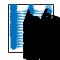

plot(net);